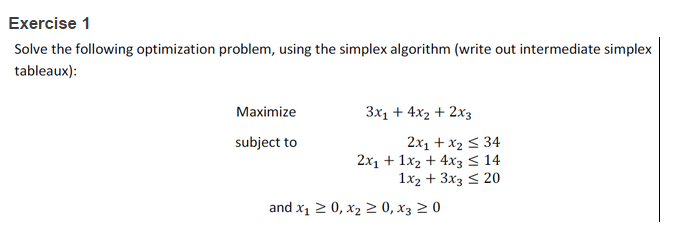

A = [   2 1 0 1 0 0 0;
        2 1 4 0 1 0 0;
        1 0 3 0 0 1 0];
b = [ 34;614;20];
c = -[3;4;2; 0; 0; 0; -1 ];
v = [4;5;6];
simplex(c,A,b,v,1)

 
Initial tableau:
  Column 1

       2       
       2       
       1       
      -3       

  Column 2

       1       
       1       
       0       
      -4       

  Column 3

       0       
       4       
       3       
      -2       

  Column 4

       1       
       0       
       0       
       0       

  Column 5

       0       
       1       
       0       
       0       

  Column 6

       0       
       0       
       1       
       0       

  Column 7

       0       
       0       
       0       
       1       

  Column 8

      34       
     614       
      20       
       0       

Pivot point:
  Column 1

       1       

  Column 2

       2       

New tableau:
  Column 1

       2       
       0       
       1       
       5       

  Column 2

       1       
       0       
       0       
       0       

  Column 3

       0       
       4       
       3       
      -2       

  Column 4

       1       
      -1       
      

ans =        0       
      34       
      20/3     
       0       
    1660/3     
       0       
       0       


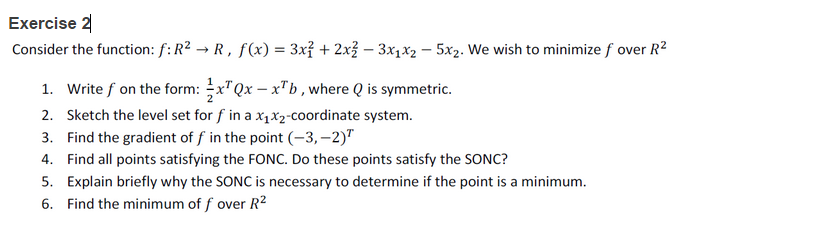

%1
syms x1 x2
f = @(x1,x2) 3*x1^2 + 2*x2^2 - 3*x1*x2 - 5*x2

f = function_handle with value:
    @(x1,x2)3*x1^2+2*x2^2-3*x1*x2-5*x2



Q = [3,-1.5;
    -1.5,2;]

Q =        3             -3/2     
      -3/2            2       


Q = Q+Q'

Q =        6             -3       
      -3              4       



b= [0;5]

b =        0       
       5       



fq = @(x) 1/2 * x' * Q *x -x'*b

fq = function_handle with value:
    @(x)1/2*x'*Q*x-x'*b



%2
% LEVEL SET
zhandle = fcontour(f)

zhandle =   FunctionContour with properties:

     Function: @(x1,x2)3*x1^2+2*x2^2-3*x1*x2-5*x2
    LineColor: 'flat'
    LineStyle: '-'
    LineWidth: 1/2
         Fill: 'off'
    LevelList: [0 20 40 60 80 100 120 140 160 180 200 220]

  Show all properties


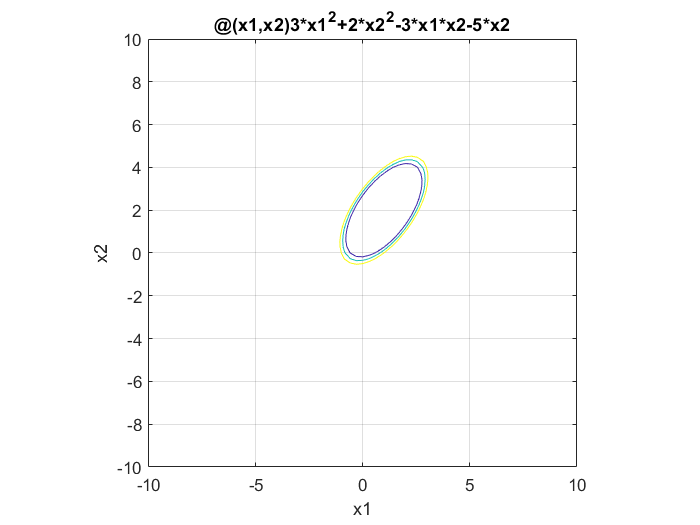

zhandle.LevelList = [1,2,3];
xlabel x1
ylabel x2
title(func2str(f))
grid on
zhandle.YRange = [-10,10];
zhandle.XRange = [-10,10];
axis equal


%3
point = [-3;-2];

g1 = diff(f,x1);
g2 = diff(f,x2);
Df = [g1 g2]

$$Df = \left(\begin{array}{cc} 6\,x_{1}-3\,x_{2} & 4\,x_{2}-3\,x_{1}-5 \end{array}\right)$$

gradient = Df'

$$gradient = \left(\begin{array}{c} 6\,\bar{x_{1}}-3\,\bar{x_{2}}\\ 4\,\bar{x_{2}}-3\,\bar{x_{1}}-5 \end{array}\right)$$

gradient = matlabFunction(gradient);
gradient(-3,-2)

ans =      -12       
      -4       



%4
%fonc
syms x1 x2
eqns = [gradient(x1,x2)==0,x1~=0, x2~=0];
sol = solve(eqns,x1,x2,'Real',true);
x = [sol.x1'; sol.x2']

$$x = \left(\begin{array}{c} 1\\ 2 \end{array}\right)$$


%sonc
syms x1 x2
df2_x1_x1 = diff(f,x1,x1);
df2_x1_x2 = diff(f,x1,x2);
df2_x2_x1 = diff(f,x2,x1);
df2_x2_x2 = diff(f,x2,x2);
D2f = [df2_x1_x1 df2_x2_x1; df2_x1_x2 df2_x2_x2]

$$D2f = \left(\begin{array}{cc} 6 & -3\\ -3 & 4 \end{array}\right)$$

det(D2f)

$$ans = 15$$

[V,D] = eig(D2f); %D gives eigen values
D

$$D = \left(\begin{array}{cc} 5-\sqrt{10} & 0\\ 0 & \sqrt{10}+5 \end{array}\right)$$

% Both positive - positive definite


## e)

The SONC states that in order for a point $\overline{x}$ to be local minimizer, then the Hessian must be *positive semidefinite*. This is required for a point to be a minimizer since it implies that the function has a point where there are no directions which result in the value of the function decreasing. Such a point is per definition a minimizer. If the function is *positive semidefinite*, then there may be several minimizers, and if the function is *positive definite*, then the function is convex and will have one minimizer.

## f)

It has been concluded that there only one point $x^\ast  =\left\lbrack \begin{array}{c}
1\\
2
\end{array}\right\rbrack$, which satisfies the FONC to be an extremizer. It has also been concluded that the SONC is satisfied, implying that the function has a minimizer.

The minimum value can therefore be determined by evaluating the function in point $x^\ast $:


$$f\left(x^\ast  \right)=f\left(1,2\right)=-5$$


f_min = f(x(1),x(2))

$$f\_min = -5$$

## Exercise 3

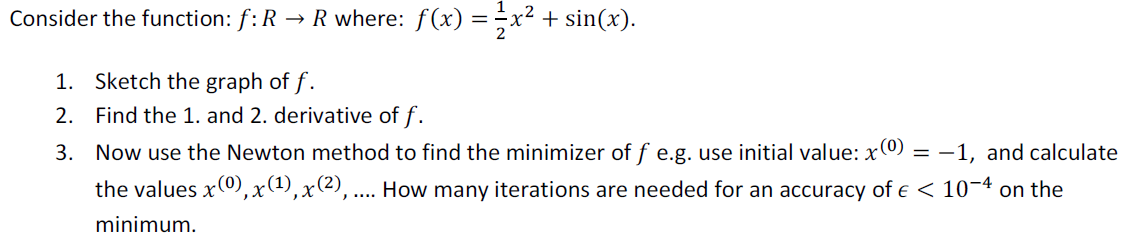

clear;


$$f\left(x\right)=\frac{1}{2}x^2 +\mathrm{sin}\left(x\right)$$


syms x
f = @(x) 1/2*x^2+sin(x)

f = function_handle with value:
    @(x)1/2*x^2+sin(x)


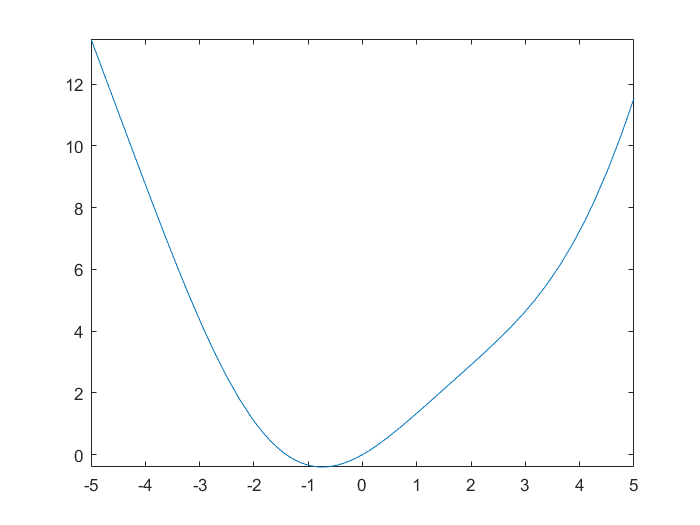

%1
fplot(f)



%2
first = diff(f,x)

$$first = x+\cos\left(x\right)$$

second = diff(f,x,x)

$$second = 1-\sin\left(x\right)$$



%3
syms x
gradient = diff(f,x)

$$gradient = x+\cos\left(x\right)$$

gradient = matlabFunction(gradient)

gradient = function_handle with value:
    @(x)x+cos(x)


D2f = diff(f,x,x)

$$D2f = 1-\sin\left(x\right)$$

F = matlabFunction(D2f)

F = function_handle with value:
    @(x)-sin(x)+1.0


x0 = -1;
N = 10 % iterations

N =       10       


x = zeros(1,N)

x =        0              0              0              0              0              0              0              0              0              0       


x(1,:) = x0;
accuracy = 10^-4;

for i=1:N
    g = gradient(x(i,1));
    x(i+1,:) = x(i,:)'-F(x(i,1))^-1*g;
    e = abs(x(i+1)-x(i));
    if e < accuracy
        break
    end
end
x

x =       -1             -1             -1             -1             -1             -1             -1             -1             -1             -1       
   -1031/1374     -1031/1374     -1031/1374     -1031/1374     -1031/1374     -1031/1374     -1031/1374     -1031/1374     -1031/1374     -1031/1374  
   -1833/2480     -1833/2480     -1833/2480     -1833/2480     -1833/2480     -1833/2480     -1833/2480     -1833/2480     -1833/2480     -1833/2480  
    -711/962       -711/962       -711/962       -711/962       -711/962       -711/962       -711/962       -711/962       -711/962       -711/962   


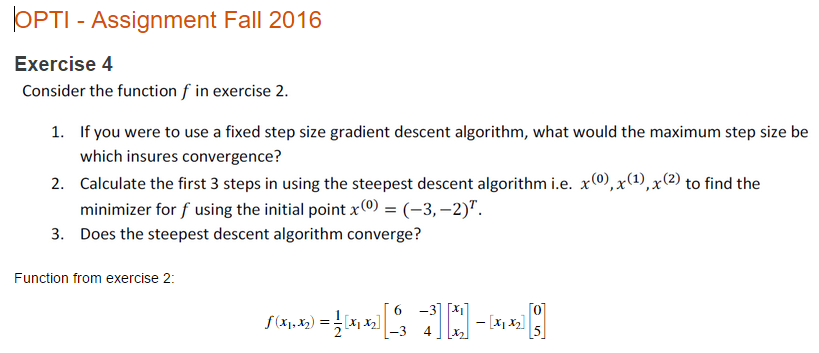


clear;
format
Q = [6 -3;
    -3 4]

Q =      6    -3
    -3     4


b = [0; 5]

b =      0
     5


f = @(x1,x2) 1/2*[x1 x2]*Q*[x1; x2] - [x1 x2]*b

f = function_handle with value:
    @(x1,x2)1/2*[x1,x2]*Q*[x1;x2]-[x1,x2]*b


## a)

The ***fixed*** ***step****-****size*** ***gradient*** ***descent*** algorithm is given by:


$$x^{\left(k+1\right)} =x^{\left(k\right)} -\alpha \text{ }\nabla f\left(x^{\left(k\right)} \right)$$


The algorithm is globally convergent when $\alpha$ is within the range:


$$0<\alpha <\frac{2}{\lambda_{\max } \left(Q\right)}$$


The maximum eigenvalue of Q is given by:

eig_max = eigs(Q,1)

eig_max = 8.1623

The range of $\alpha$ is then:


$$0<\alpha <\frac{2}{8\ldotp 162}$$


%b
syms x1 x2
Df = [diff(f,x1) diff(f,x2)]

$$Df = \left(\begin{array}{cc} 6\,x_{1}-3\,x_{2} & 4\,x_{2}-3\,x_{1}-5 \end{array}\right)$$

gradient = matlabFunction(Df)

gradient = function_handle with value:
    @(x1,x2)[x1.*6.0-x2.*3.0,x1.*-3.0+x2.*4.0-5.0]



syms x1 x2
D2f = [diff(f(x1,x2),x1,x1) diff(f(x1,x2),x2,x1); diff(f(x1,x2),x1,x2) diff(f(x1,x2),x2,x2)]

$$D2f = \left(\begin{array}{cc} 6 & -3\\ -3 & 4 \end{array}\right)$$

format longE
x0 = [-3; -2];

N = 2 % iterations

N =      2


x = zeros(N,length(x0));
g = zeros(N,length(x0));
x(1,:) = x0;

for i=1:N
    g(i,:) = gradient(x(i,1),x(i,2));
    x(i+1,:) = x(i,:)'-(g(i,:)*g(i,:)')/(g(i,:)*Q*g(i,:)')*g(i,:)';
end
x

x =     -3.000000000000000e+00    -2.000000000000000e+00
                         0    -1.000000000000000e+00
    -5.000000000000000e-01     5.000000000000000e-01


g

g =    -12    -4
     3    -9


format

## c)

Per Theorem 8.2 in the course book "An Introduction to Optimization", the convergence of the steepest descent algorithm is independent of the starting point. The algorithm will therefore converge.